Simulazine gusti attuatori

% Parametri del sensore ideale
t = linspace(0, 10, 100); % tempo
steady_value = 0;
k=3; %tasso di tabilizzazione

% Parametri della sovraelongazione
overshoot_amplitude = 5; % Ampiezza della sovraelongazione
d = 0.09; % Smorzamento
omega = 0.5; % Frequenza della sovraelongazione

ideal_output =5 + steady_value*(1- exp(-k*t))+overshoot_amplitude ...
    * exp(-d * t) .* sin(omega * t); % Uscita ideale

Lock in place

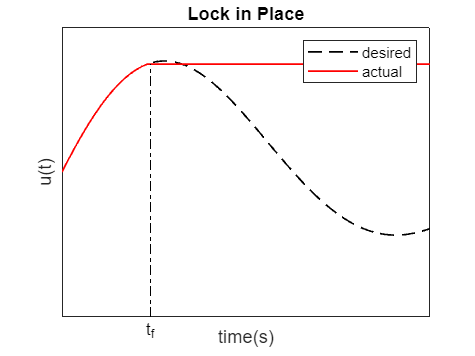

lock_in_place = ideal_output;
lock_in_place(25:end) = lock_in_place(24);

figure;
plot(t, ideal_output, 'k--', 'LineWidth', 1); hold on;
plot(t, lock_in_place, 'r-', 'LineWidth', 1);
plot([2.4, 2.4], [0, lock_in_place(24)], 'k-.', 'LineWidth', 0.6);

% Etichetta il tempo t_f sull'asse x
text(2.4, -0.1, sprintf('t_f', 2.4), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 10);


xlabel('time(s)');
ylabel('u(t)');
legend('desired', 'actual');
title('Lock in Place');
set(gca, 'XTick', [], 'YTick', []);
grid off;

Float

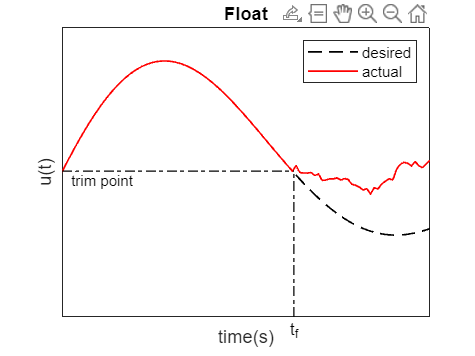

float = ideal_output;
% Segmento del guasto (dopo un certo tempo)
free_response_duration = 64:length(t); % Indice di inizio del galleggiamento
noise = 2*randn(size(free_response_duration)); % Rumore bianco

% Filtraggio del rumore (moving average)
window_size = 20; % Finestra di media mobile
smooth_noise = filter(ones(1, window_size) / window_size, 1, noise);

% Aggiunta del rumore filtrato al valore finale del segnale ideale
float(free_response_duration) = float(63) + smooth_noise;

t_f = 6.3;

figure;
plot(t, ideal_output, 'k--', 'LineWidth', 1); hold on;
plot(t, float, 'r-', 'LineWidth', 1);
plot([6.3, 6.3], [0, float(63)], 'k-.', 'LineWidth', 0.6);
plot([0, t_f], [float(63), float(63)], 'k-.', 'LineWidth', 0.6);


% Etichetta il tempo t_f sull'asse x
text(t_f, -0.1, sprintf('t_f', t_f), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 10);
% Etichetta trimmer point sull'asse y
text(1.1, float(63), sprintf('trim point', t_f), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 9);
xlabel('time(s)');
ylabel('u(t)');
legend('desired', 'actual');
set(gca, 'XTick', [], 'YTick', []);
title('Float');
grid off;

Hardover

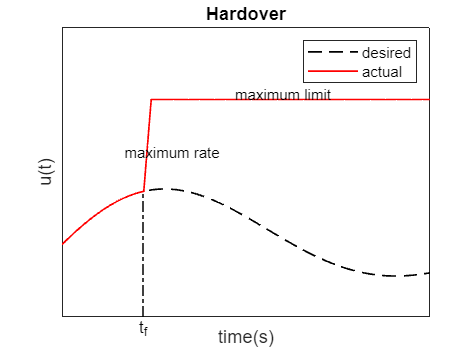

hardover = ideal_output;
hardover(24) = (hardover(23)+15)/2;
hardover(25:end) = 15;

t_f = 2.2;

figure;
plot(t, ideal_output, 'k--', 'LineWidth', 1); hold on;
plot(t, hardover, 'r-', 'LineWidth', 1);
plot([t_f, t_f], [0, hardover(22)], 'k-.', 'LineWidth', 0.6);
%plot([0, t_f], [float(63), float(63)], 'k-.', 'LineWidth', 0.8);

% Fix the axes sizes
axis([0 10 0 20])

% Etichetta il tempo t_f sull'asse x
text(t_f, -0.1, sprintf('t_f', t_f), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 10);

% Etichetta maximum rate sull'asse y
text(3, 12, sprintf('maximum rate', t_f), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 9);

% Etichetta maximum limi sull'asse y
text(6, 16, sprintf('maximum limit', t_f), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 9);

xlabel('time(s)');
ylabel('u(t)');
legend('desired', 'actual');
set(gca, 'XTick', [], 'YTick', []);
title('Hardover');
grid off;

Loss of effectiveness

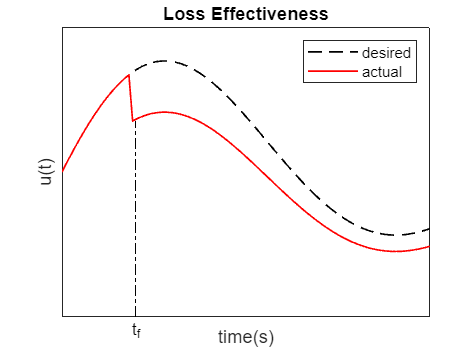

fault_loss_effectiveness = ideal_output;
fault_loss_effectiveness(20:end) = 0.8 * ideal_output(20:end); % Riduzione guadagno


figure;
plot(t, ideal_output, 'k--', 'LineWidth', 1); hold on;
plot(t, fault_loss_effectiveness, 'r-', 'LineWidth', 1);
plot([2, 2], [0, fault_loss_effectiveness(20)], 'k-.', 'LineWidth', 0.6);

% Etichetta il tempo t_f sull'asse x
text(2, -0.1, sprintf('t_f', 2), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 10);


xlabel('time(s)');
ylabel('u(t)');
legend('desired', 'actual');
title('Loss Effectiveness');
set(gca, 'XTick', [], 'YTick', []);
grid off;

## Simulazine gusti sensori

% Parametri del sensore ideale
t = linspace(0, 10, 100); % tempo
k=3; %tasso di tabilizzazione

ideal_output_sensor =5 + 1*(1- exp(-k*t))+5 ...
    * exp(-0.2 * t) .* sin(0.7 * t); % Uscita ideale

Bias Fault

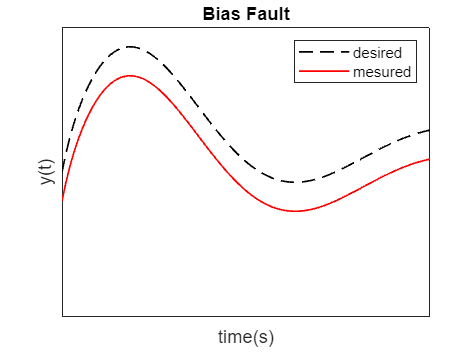

bias = ideal_output_sensor - 1;

figure;
plot(t, ideal_output_sensor, 'k--', 'LineWidth', 1); hold on;
plot(t, bias, 'r-', 'LineWidth', 1);
axis([0 10 0 10])
xlabel('time(s)');
ylabel('y(t)');
legend('desired', 'mesured');
set(gca, 'XTick', [], 'YTick', []);
title('Bias Fault');
grid off;

Freezing

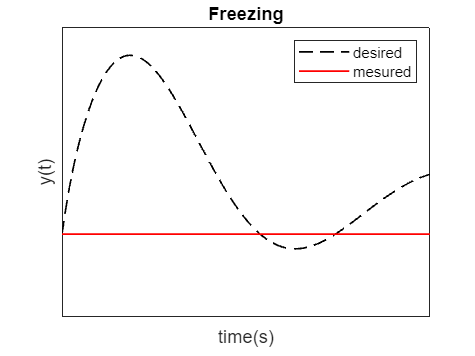

freezing = ideal_output_sensor;
freezing(1:end) = ideal_output_sensor(1);


figure;
plot(t, ideal_output_sensor, 'k--', 'LineWidth', 1); hold on;
plot(t, freezing, 'r-', 'LineWidth', 1);
axis([0 10 3 10])
xlabel('time(s)');
ylabel('y(t)');
legend('desired', 'mesured');
set(gca, 'XTick', [], 'YTick', []);
title('Freezing');
grid off;

Drift

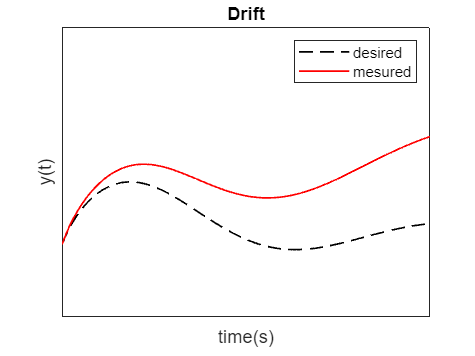

drift = ideal_output_sensor + 0.6*t;

figure;
plot(t, ideal_output_sensor, 'k--', 'LineWidth', 1); hold on;
plot(t, drift, 'r-', 'LineWidth', 1);
axis([0 10 0 20])
xlabel('time(s)');
ylabel('y(t)');
legend('desired', 'mesured');
set(gca, 'XTick', [], 'YTick', []);
title('Drift');
grid off;

Loss of accuracy

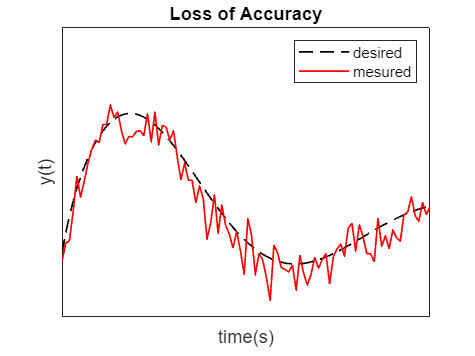

% Generazione di dati casuali da distribuzione normale
data = randn(1, 100); % Ad esempio, 1000 campioni

% Normalizzazione tra 0 e 0.5
min_val = -0.4; % Valore minimo
max_val = 0.4; % Valore massimo
data_normalized = (data - min_val) / (max_val - min_val) * (-0.4);


loss_of_accuracy = ideal_output_sensor + data_normalized;



figure;
plot(t, ideal_output_sensor, 'k--', 'LineWidth', 1); hold on;
plot(t, loss_of_accuracy, 'r-', 'LineWidth', 1);
axis([0 10 3 12])
xlabel('time(s)');
ylabel('y(t)');
legend('desired', 'mesured');
set(gca, 'XTick', [], 'YTick', []);
title('Loss of Accuracy');
grid off;

Calibration

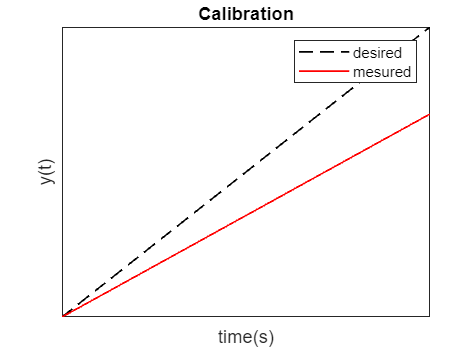

c = 0.7; 
calibration = c*t;

figure;
plot(t, t, 'k--', 'LineWidth', 1); hold on;
plot(t, calibration, 'r-', 'LineWidth', 1);
axis([0 10 0 10])
xlabel('time(s)');
ylabel('y(t)');
legend('desired', 'mesured');
set(gca, 'XTick', [], 'YTick', []);
title('Calibration');
grid off;